clear

Path = {    'DeepLearningData/Normal/A',...
    'DeepLearningData/Normal/D',...
    'DeepLearningData/Normal/F',...
    'DeepLearningData/Normal/H',...
    'DeepLearningData/Normal/K',...
    'DeepLearningData/Normal/L',...
    'DeepLearningData/Normal/M',...
    'DeepLearningData/Normal/N',...
    'DeepLearningData/Normal/T',...
    'DeepLearningData/Normal/Y'};

Path2 = {    'DeepLearningData/W2/A',...
    'DeepLearningData/W2/D',...
    'DeepLearningData/W2/F',...
    'DeepLearningData/W2/H',...
    'DeepLearningData/W2/K',...
    'DeepLearningData/W2/L',...
    'DeepLearningData/W2/M',...
    'DeepLearningData/W2/N',...
    'DeepLearningData/W2/T',...
    'DeepLearningData/W2/Y'};

imds = imageDatastore(Path,'IncludeSubfolders',true,'LabelSource','foldernames');
imdsTest = imageDatastore(Path2,'IncludeSubfolders',true,'LabelSource','foldernames');

numTrainFiles = 400;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');

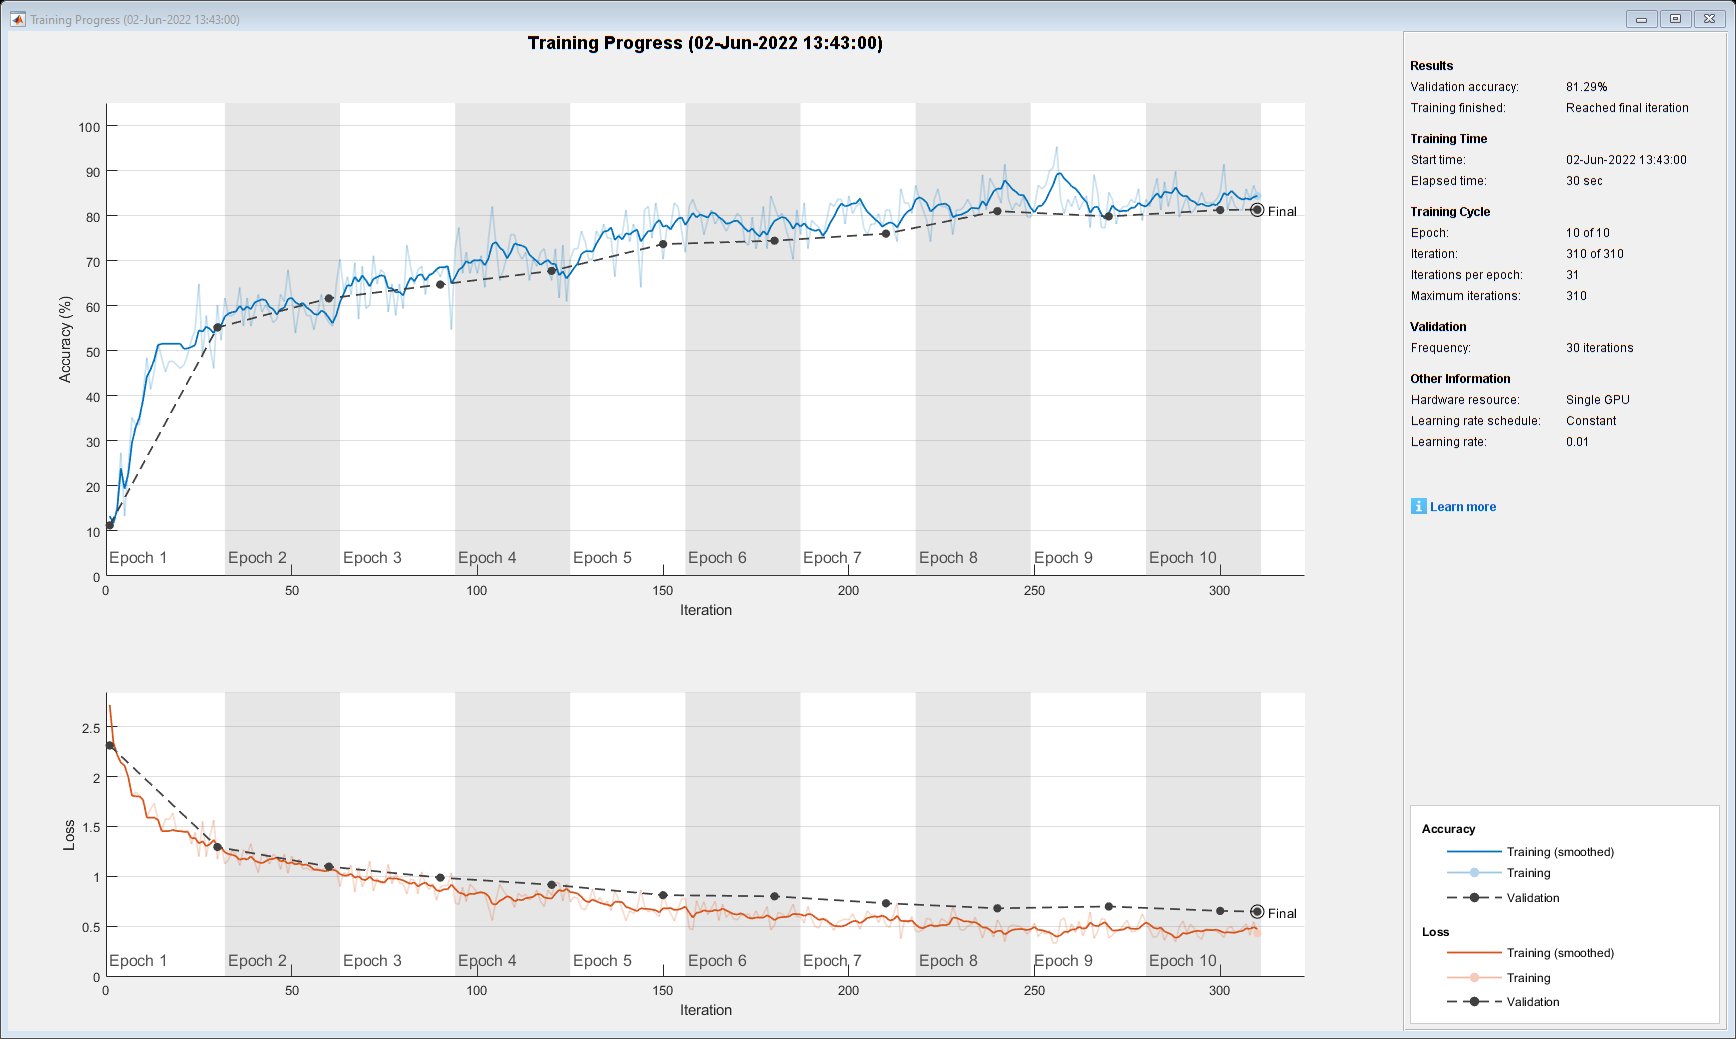



layers = [
imageInputLayer([150 150 1])
convolution2dLayer(3,8,'Padding','same')
batchNormalizationLayer
reluLayer
maxPooling2dLayer(2,'Stride',2)
convolution2dLayer(3,16,'Padding','same')
batchNormalizationLayer
reluLayer
maxPooling2dLayer(2,'Stride',2)
convolution2dLayer(3,16,'Padding','same')
batchNormalizationLayer
fullyConnectedLayer(10)
reluLayer
fullyConnectedLayer(10)
softmaxLayer
classificationLayer];

net = nettrainset(imdsTrain,imdsValidation,layers);


[accuracy,YPred,YValidation] = getaccontest(net,imdsTest)

accuracy = 0.6047

YPred = 6000×1 categorical array
     D 
     D 
     D 
     D 
     D 
     D 
     D 
     D 
     D 
     A 
     M 
     D 
     D 
     D 
     D 
     D 
     D 
     D 
     A 
     H 
     D 
     D 
     A 
     D 
     D 
     A 
     D 
     D 
     D 
     D 


YValidation = 6000×1 categorical array
     A 
     A 
     A 
     A 
     A 
     A 
     A 
     A 
     A 
     A 
     A 
     A 
     A 
     A 
     A 
     A 
     A 
     A 
     A 
     A 
     A 
     A 
     A 
     A 
     A 
     A 
     A 
     A 
     A 
     A 


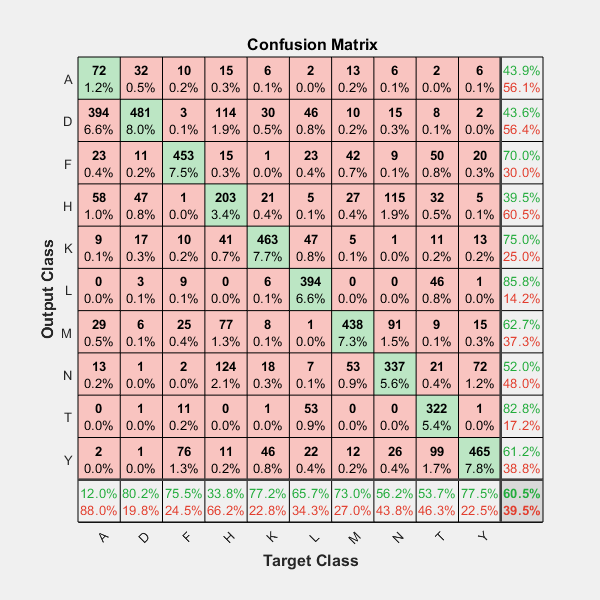


plotconfusion(YValidation,YPred)

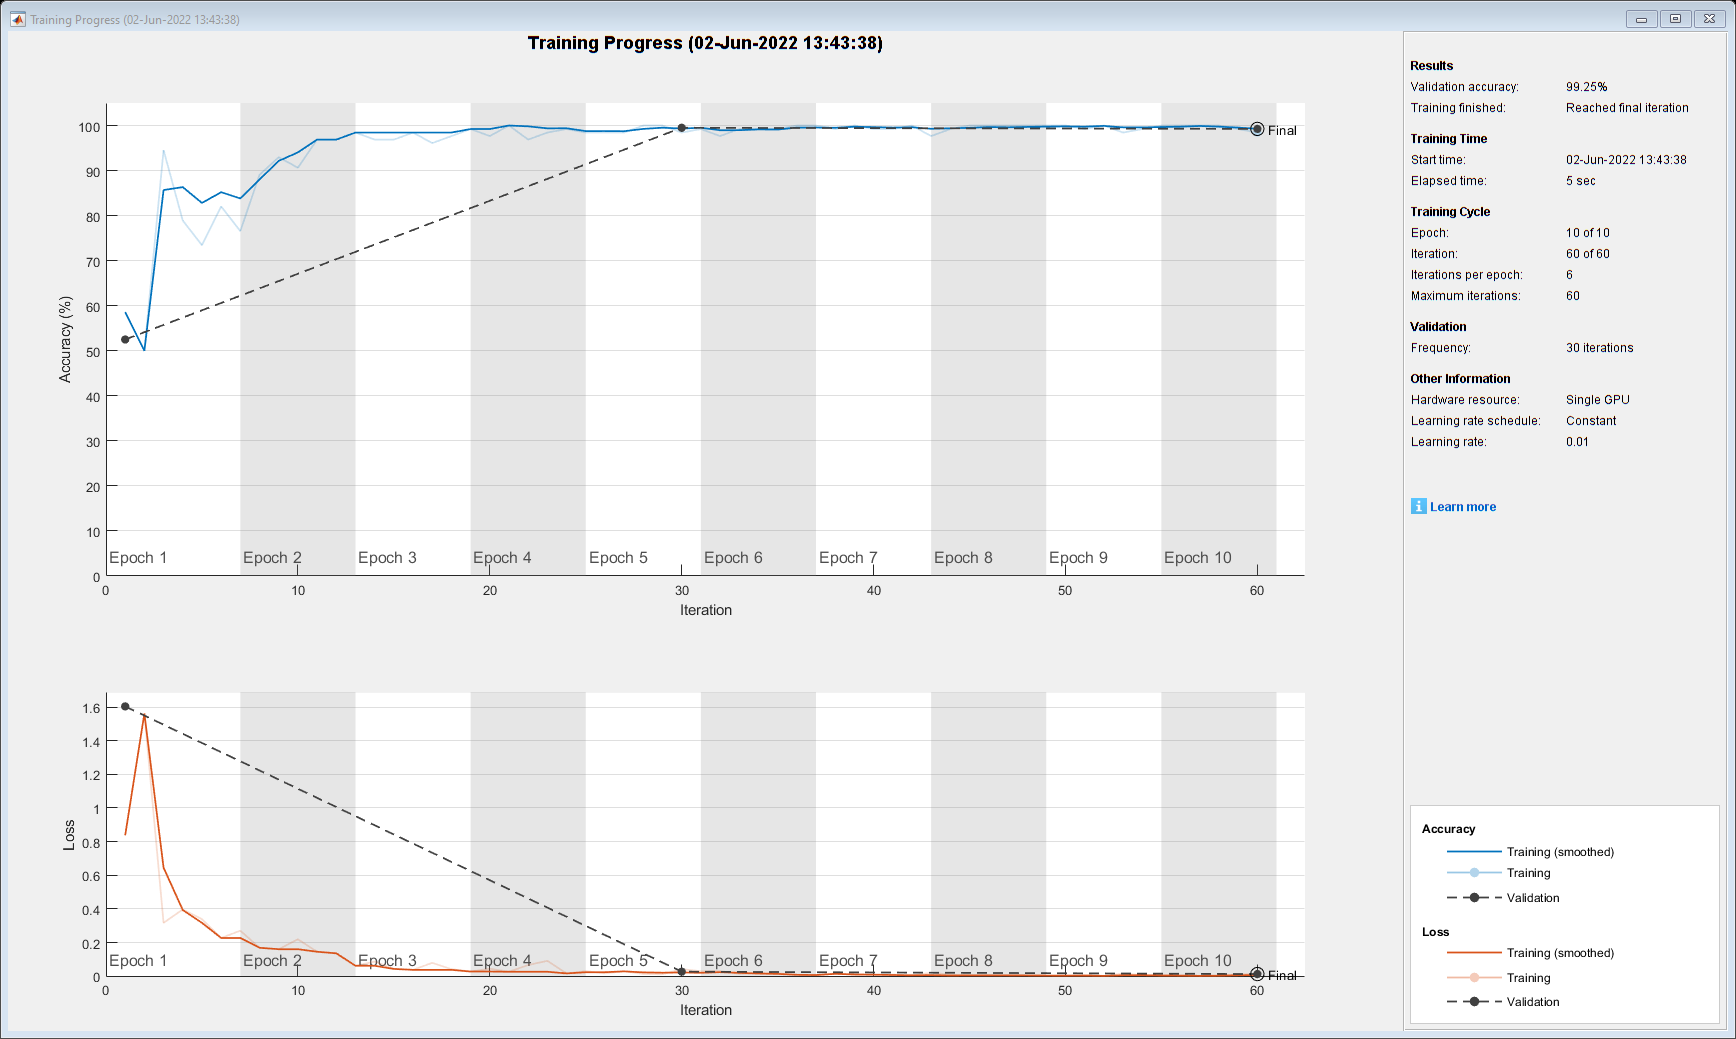

Path3 = {    'DeepLearningDataCaptcha/Normal/M',...
    'DeepLearningDataCaptcha/Normal/T'};

Path4 = {    'DeepLearningDataCaptcha/W2/M',...
    'DeepLearningDataCaptcha/W2/T'};

imds2 = imageDatastore(Path3,'IncludeSubfolders',true,'LabelSource','foldernames');
imdsTest2 = imageDatastore(Path4,'IncludeSubfolders',true,'LabelSource','foldernames');

numTrainFiles = 400;
[imdsTrain2,imdsValidation2] = splitEachLabel(imds2,numTrainFiles,'randomize');


layers2 = [
imageInputLayer([150 150 1])
convolution2dLayer(3,8,'Padding','same')
batchNormalizationLayer
reluLayer
maxPooling2dLayer(2,'Stride',2)
convolution2dLayer(3,16,'Padding','same')
batchNormalizationLayer
reluLayer
maxPooling2dLayer(2,'Stride',2)
convolution2dLayer(3,16,'Padding','same')
batchNormalizationLayer
fullyConnectedLayer(10)
reluLayer
fullyConnectedLayer(2)
softmaxLayer
classificationLayer];

net2 = nettrainset(imdsTrain2,imdsValidation2,layers2);


[accuracy2,YPred2,YValidation2] = getaccontest(net2,imdsTest2)

accuracy2 = 0.9767

YPred2 = 1200×1 categorical array
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 


YValidation2 = 1200×1 categorical array
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 
     M 


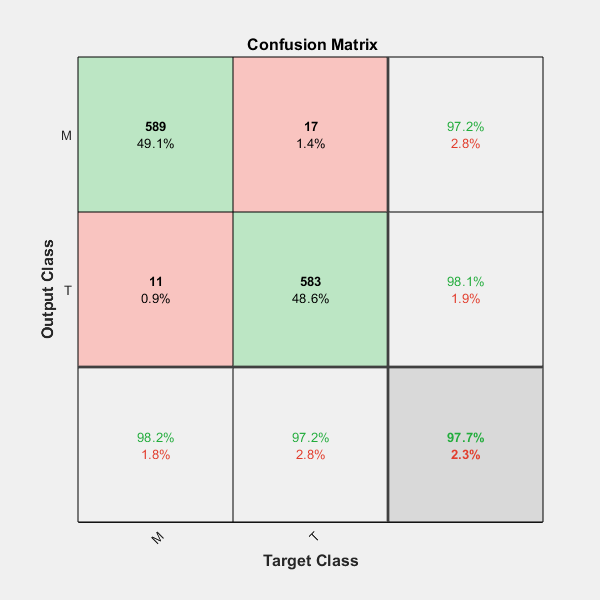

plotconfusion(YValidation2,YPred2)